# Adaptive filters

**Exemplary applications**: adaptive interference cancelation (AIC), adaptive echo cancellation (AEC), active noise control (ANC), adaptive signal enhancement (denoising) (ASE). Below we present only **FIR (N)LMS adaptive filters**.

## Basic theory

Adaptive filter is a computation module having two input signals:

- $d(n)$   -  desired/reference one,

- $x(n)$   -  to be adaptively filtered,

and two output signals:

- $y(n)= \sum_{k=0}^{M} h_k(n) x(n-k)$  - adaptive filtration of $x(n)$, filter weights are changing,

- $e(n)=d(n)-y(n)$    -  error signal.

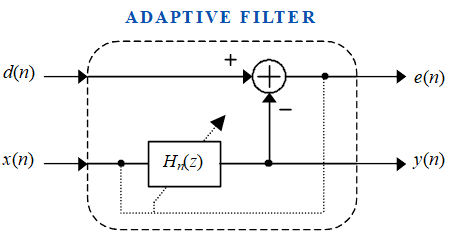

**Figure:** Block diagram of the adaptive filter

The role of the filter is to make the signal $y(n)$ as much as possible similar to the signal $d(n)$:


$$y(n) \rightarrow d(n)$$
 

Adaptive changing of filter weights and their frequency response has to ensure minimization of a filter cost function:

- $J(n)=e^{2}(n)$ - *Normalized Least Mean Squares* **(N)LMS**: squared momentum error $e(n)$ of adjustment (fitting) the signal $y(n)$ to the signal $d(n)$,   ,

- $J(n)=\sum _{k=0}^{+\infty}\lambda^{k} \cdot e^2(n-k), \;\; \lambda \leq 1$ - *Weighted Recursive Least Squares* **RLS/WRLS**: weighted sum of the present and previous values of the squared error $e(n)$.

For the FIR LMS filter such values of $h_k(n)$ are searched by adaptation process which ensure for every moment $n$ minimization of the following cost function:


$$J(n) = \left( d(n) - y(n) \right)^2 = \left( d(n) - \sum_{k=0}^{M}{ h_k(n)x(n-k)} \right) ^2}$$


In order to find them, derivative of the function $J(n)$ in respect to each filter coefficient is calculated:

        $\frac{dJ(n)}{dh_{k}(n)} = 2 \cdot e(n) \cdot \frac{d}{dh_{k}(n)} \left[ d(n) - h_{0}(n) \cdot x(n-0) - ... - h_{M}(n) \cdot x(n-M) \right]$,

        $\frac{dJ(n)}{dh_{k}(n)} = -2*e(n) \cdot x(n-k)$,

and next, during adaptation, filter coefficient values are changed in opposite direction to the function growth, i.e. to its gradient (note minus sign below):

        $h_{k}(n+1) = h_{k}(n) - \frac{dJ(n)}{dh_{k}}= h_{k}(n) +2 \cdot \mu \cdot e(n) \cdot x(n-k)$,

**FOR ABIMITIOUS STUDENTS ONLY.** Values of the optimal filter weights, valid for stationary case, were derived by Wiener:


$$\mathbf{h}_{opt} = \mathbf{R}_{xx}^{-1} \cdot \mathbf{r}_{dx}$$


where:

- $\mathbf{R}_{xx}$ - denotes auto-correlation matrix of the signal $x(n)$,

- $\mathbf{r}_{dx}$ - is a vector of cross-correlation between the signals $d(n)$ and $x(n)$.

Maximum value of adaptation speed coefficient $\mu$ is constrained by the following top-bounding equation:

$0 < \mu < \frac{2}{\lambda_{max}}$,

where $\lambda_{max}$ is the biggest eigen-value of the matrix $\mathbf{R}_{xx}$ - for larger values of $\mu$ the LMS adaptive filter becomes unstable. The convergence speed is the highest when

$\lambda_{max}/\lambda_{max} \approx 1$.

i.e. when $x(n)$ is a pure noise. In an RLS adaptive filter the optimal Wiener solution is iteratively solved, i.e. the matrix $\mathbf{R}_{xx}^{-1}$ is initially estimated and adaptively updated.

## Examplary usage

In this laboratory we will concentrate only on (N)LMS adaptive filters and consider only two the most typical adaptive filter applications:

- **adaptive correlation / interference canceling (ACC/AIC)** between two signals;

- **linear-prediction-based adaptive signal / telecommunication line enhancement** **(ASE/ALE)**.

**ACC/AIC.** On the filter input we have in this case a disturbed signal  $d(n)=s(n)+\varepsilon_1(n)$ and non-perfect, reference pattern of the disturbance $x(n)=\varepsilon_2(n)$. The filter tries to fit the possessed disturbance pattern $\varepsilon_2(n)$to the disturbance $\varepsilon_1(n)$, present in $d(n)$, by adaptive filtering, and subtract it: 


$$e(n)=d(n)-y(n)=s(n)+\varepsilon_1(n) -\text{adapt}(\varepsilon_2n)) =  s(n) + \left( \varepsilon_1(n) - \hat{\varepsilon}_1(n) \right)$$


For example, speech of airplane pilot is interfered by motor whir and recorded by one microphone, while non-ideal pattern of the whir is captured by the second microphone (amplified/attenuated and delayed/stepped-up). The whir reference is adaptively fitted to the whir disturbing a pilot and subtracted from the currupted pilot speech.

**ASE/ALE**. Signal $x(n)=d(n-1)$, i.e. it is a delayed version of $d(n).$ Therefore, the adaptive filter is working as linear predictor and is trying to predict next sample of the signal $d(n)$. Since it is not possible for noisy components of $d(n)$, the processed/filtered signal $y(n) $ becomes a denoised version of $d(n)$.

**Analyze the Matlab program presented below.**  It demonstrates adaptive FIR LMS filter usage in two main scenarios, briefly characterized above.

Run the program, observe figures. First set `test=1`, then `test=2`. Try to find better values of `N` (filter length) and `mi` (adaptation speed coefficient). "Better" means: giving faster adaptation and stronger interference rejection. Use LMS and normalized LMS (NLMS) adaptive filter. Record your own speech. Add to it: 1) sinusoid (case 1), and 2) noise (case 2). Check how the filter is removing these disturbances. Try to select optimal values of filter parameters.

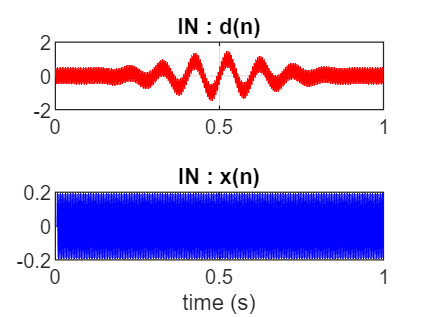

clear all; close all;

test=1;      % two adaptive scenarios: 1=ACC/AIC, 2=ASE/ALE

% ##### Input signals and values of adaptive filter parameters #####

fpr = 1000;                                  % sampling frequency
Nx = fpr;                                    % number of samples, 1 secund
dt = 1/fpr; t = 0 : dt :(Nx-1)*dt;           % time
f = 0 : fpr/1000 : fpr/2;                    % frequency

if(test==1) % Scenario #1 ACC/AIC - adaptive correlation/interference cancelling
   M = 50;                                   % number of filter weights
   mi = 0.1;                                 % adaptation speed ( 0<mi<1)
   s = sin(2*pi*10*t).*exp(-25*(t-0.5).^2);  % signal: sine*gaussoid, ECG or speech
   z = sin(2*pi*200*t);                      % interference: harmonic, engine wirr
   d = s + 0.5*z;                            % signal + scaled interference
   x = 0.2*[zeros(1,5) z(1:end-5)];          % delayed and scaled interference "copy"
else  % Scenario #2 ALE/ASE - adaptive line/signal enhancement (denoising) 
   M = 10;                                   % number of filter weights
   mi = 0.0025;                              % adaptation speed ( 0<mi<1)
   s = sin(2*pi*10*t);                       % signal: sine, ECG or speech
   z = 0.3*rand(1,Nx);                       % disturbing noise
   d = s + z;                                % signal disturbed by noise
   x = [ 0, d(1:end-1)];                     % delayed "copy" of the disturbed signal
end   
        figure;
        subplot(211); plot(t,d,'r'); grid; title('IN : d(n)');
        subplot(212); plot(t,x,'b'); grid; title('IN : x(n)'); xlabel('time (s)');

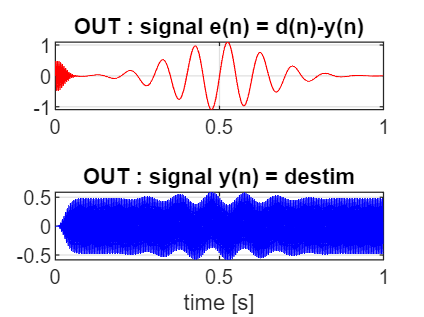


% ###### Adaptive filtering ######

bx=zeros(M,1);           % initialization: buffer fo input signal x(n) samples
h  = zeros(M,1);         % initialization: filter weights
y  = zeros(1,Nx);        % empty output, signal y(n) 
e  = zeros(1,Nx);        % empty output, signal e(n)
for n = 1 : length(x)              % main loop
  % n                              % loop index
    bx = [ x(n); bx(1:M-1) ];      % putting new sample of x(n) into the buffer
    y(n) = h' * bx;                % filtering x(n), i.e. estimation of d(n)
    e(n) = d(n) - y(n);            % estimation error
    h = h + ( 2*mi * e(n) * bx );            % LMS  - filter weights adaptation
  % h = h + mi/(0.0001+bx'*bx) * e(n) * bx;  % NLMS - filter weights adaptation 
        if(0) % Observation of filter weights change and filter amplitude response change
            subplot(211); stem(h); xlabel('n'); title('h(n)'); grid;
            subplot(212); plot(f,abs(freqz(h,1,f,fpr))); xlabel('f (Hz)');
            title('|H(f)|'); grid; pause
        end   
end
  
% ###### Figures ###### - output signals from adaptive filter

        figure;
        subplot(211); plot(t,e,'r'); grid; title('OUT : signal e(n) = d(n)-y(n)');
        subplot(212); plot(t,y,'b'); grid; title('OUT : signal y(n) = destim');
        xlabel('time [s]');

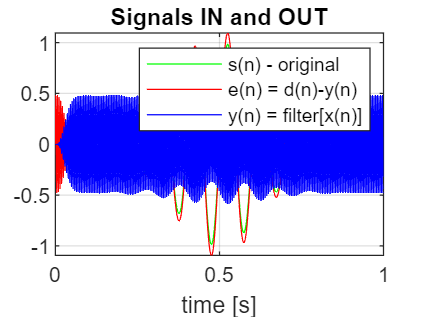


        figure; subplot(111); plot(t,s,'g',t,e,'r',t,y,'b');
        grid; xlabel('time [s]'); title('Signals IN and OUT');
        legend('s(n) - original','e(n) = d(n)-y(n)','y(n) = filter[x(n)]');